# JoyStick Demo - Gator Summer 2022

### REV A

Joystick Demo to drive the Gator via a usb connected joystick to the main system

%%% Path Declaration
addpath(...
    "ACT\",...
    "GPSCOORDS\",...
    "SENSE\",...
    "SETUP\",...
    "SHUTDOWN\",...
    "THINK\")
disp("FOLDER PATHS ADDED")

FOLDER PATHS ADDED


%%$ Variable Decleration
controlFlag = 1;                                   % Start Control counter
sampleTime = 0.0001;                                  % Sample time [s]
t = 0:sampleTime:100;                              % Time array
r = rateControl(1/sampleTime);                     % reset control loop  rate
reset(r);                                          % reset loop time to zero

joystickOpt = true;

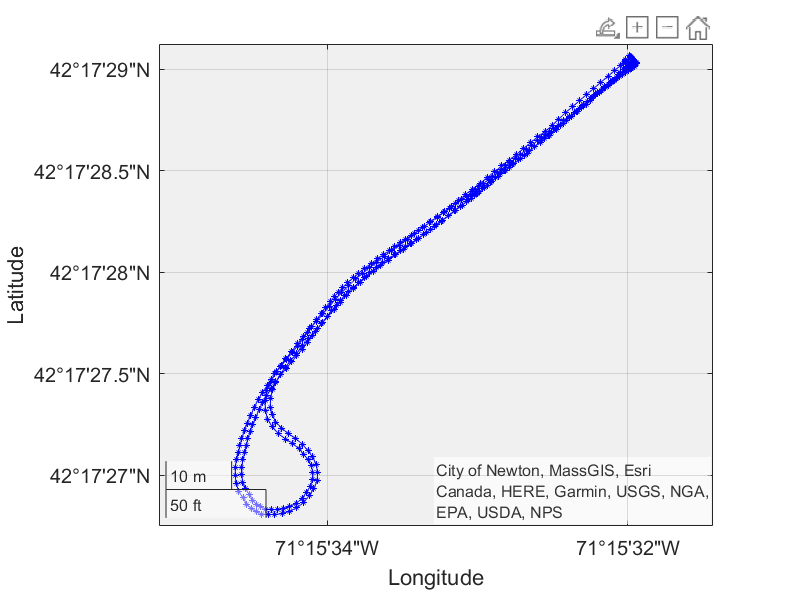

%%% SETUP 
hold on
[lat1,lon1]=PlotGPSlog("C:\Users\Skull\Documents\GatorTemp\RTK_GPS\GPS_Right_Data.ubx");
[lat2,lon2]=PlotGPSlog("C:\Users\Skull\Documents\GatorTemp\RTK_GPS\GPS_Left_Data.ubx");

middlelat=mean([lat1; lat2]);

Error using vertcat
Dimensions of arrays being concatenated are not consistent.

middlelon=mean([lon1; lon2]);
hold on
plot(lat1,lon1)
plot(lat2,lon2)
hold off
% intersection=find(y1==t);


objects = setupGPSDemo('COM11');

%%% MAIN
while (controlFlag > 0)           % loop for number of elements in t
    tic
    %controlTime = r.TotalElapsedTime;    % running register of control loop time
    senseobjects=sense();
                           
    controlFlag = controlFlag+1;         % increment loops
 %waitfor(r);  % wait for loop cycle to complete  
end 

%%% SHUTDOWN
clear